clear; close all; clc;

tester_model = 'TESTER_Brown_Full_Sim';
full_model = 'Brown_Full_Sim';
disp('Model is significantly differnt from given model (see above)/n many test case parameters had to be ajusted')

Model is significantly differnt from given model (see above)/n many test case parameters had to be ajusted


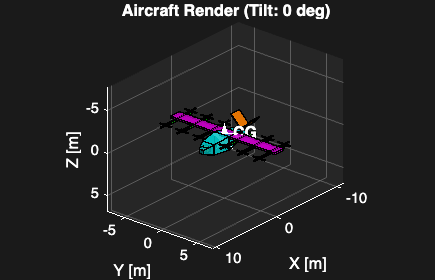

[Mass, CG, J, wing, tailL, tailR, prop, compData, tilt_angle] = init_from_full_sim();
render_aircraft(compData, CG, tilt_angle);

--------------------------------------------------
Case 1 - UnstableAxis
--------------------------------------------------
  Model:            TESTER_Brown_Full_Sim
  Simulation Time:  10 s
  Initial Position: [0  0  -1000] m
  Initial Velocity: [0  0  0] m/s
  Initial Euler:    [0  0  0] deg
  Initial Omega:    [1  0.01  0.01] rad/s
  Gravity:          [0  0  0] m/s^2
  Fext_B:           [0  0  0] N
  Mext_B:           [0  0  0] N-m
 


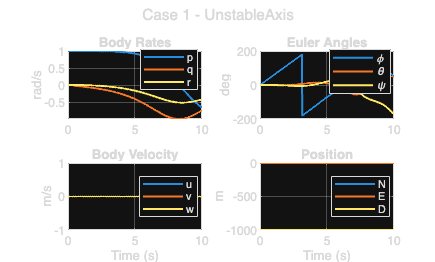

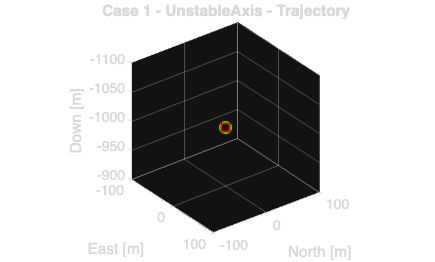

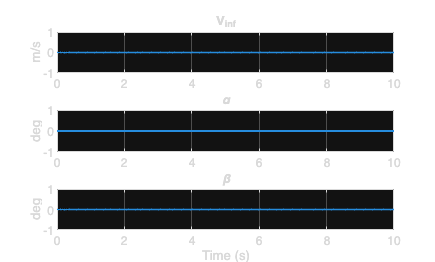

Spins about axis and couples into motion in other axes as expected



Motor_RPMs = zeros(12,1);
Tilt_angles = zeros(6,1);

%% Test cases


TC1.name = 'Case 1 - UnstableAxis';
TC1.model = tester_model;
TC1.t_stop = 10;
TC1.pos_init = [0;0;-1000];
TC1.V_init = [0;0;0];
TC1.eul_init_deg = [0;0;0];
TC1.omega_init = [1;1e-2;1e-2];
TC1.g = 0;
TC1.Fext_B = [0;0;0];
TC1.Mext_B = [0;0;0];
TC1.Motor_RPMs = Motor_RPMs;
TC1.Tilt_angles = Tilt_angles;
TC1.note = 'Spins about axis and couples into motion in other axes as expected';

TC2.name = 'Case 2 - OutsideLoop';
TC2.model = tester_model;
TC2.t_stop = 10;
TC2.pos_init = [0;0;-1000];
TC2.V_init = [13;0;0];
TC2.eul_init_deg = [0;0;0];
TC2.omega_init = [0;1;0];
TC2.g = 0;
TC2.Fext_B = [0;0;-70000];
TC2.Mext_B = [0;0;0];
TC2.Motor_RPMs = Motor_RPMs;
TC2.Tilt_angles = Tilt_angles;
TC2.note = 'DLoops as expected, not a perfect circle/nbecause I didnt calculate the right force';

TC3.name = 'Case 3 - ForceField';
TC3.model = tester_model;
TC3.t_stop = 10;
TC3.pos_init = [0;0;-1000];
TC3.V_init = [13;0;0.25];
TC3.eul_init_deg = [0;0;0];
TC3.omega_init = [0;0;0];
TC3.g = 9.81;    %gravity changed to positive to make vector pointing down
TC3.Fext_B = [0;0;-4.7088];
TC3.Mext_B = [0;0;0];
TC3.Motor_RPMs = Motor_RPMs;
TC3.Tilt_angles = Tilt_angles;
TC3.note = 'Drops due to gravity being stronger than the external force';

TC4.name = 'Case 4 - Roll Damping';
TC4.model = full_model;
TC4.t_stop = 10;
TC4.pos_init = [0;0;-1000];
TC4.V_init = [250;0;0];
TC4.eul_init_deg = [0;0;0];
TC4.omega_init = [0.3;0;0];
TC4.g = [0;0;0];
TC4.Fext_B = [0;0;0];
TC4.Mext_B = [0;0;0];
TC4.Motor_RPMs = Motor_RPMs;
TC4.Tilt_angles = Tilt_angles;
TC4.note = 'Stability seems to be different from prop plane likely due to V tail /nSeems like ti has a stability simmilar to a paper airplane that/n speeds while dropping then pitches and slows, before dropping again';

TC5.name = 'Case 5 - Beta to Yaw';
TC5.model = full_model;
TC5.t_stop = 10;
TC5.pos_init = [0;0;-1000];
TC5.V_init = [250;25;0];
TC5.eul_init_deg = [0;0;0];
TC5.omega_init = [0;0;0];
TC5.g = [0;0;0];
TC5.Fext_B = [0;0;0];
TC5.Mext_B = [0;0;0];
TC5.Motor_RPMs = Motor_RPMs;
TC5.Tilt_angles = Tilt_angles;
TC5.note = 'again lots of coupling in the axes that cant be simply explained due to V tial/n seeing the same paper airplane synamics here';

TC6.name = 'Final Validation - Stable 6DOF';
TC6.model = full_model;
TC6.t_stop = 10;
TC6.pos_init = [0;0;-1000];
TC6.V_init = [200;0.25;0.25];
TC6.eul_init_deg = [10;10;0];
TC6.omega_init = [1e-2;1;1e-2];
TC6.g = [0;0;-9.81];
TC6.Fext_B = [0;0;0];
TC6.Mext_B = [0;0;0];
TC6.Motor_RPMs = 1500 * ones(12,1);
TC6.Tilt_angles = 90 * ones(6,1);
TC6.note = 'Motors seem to bring plane upwards - Aircraft is much more complex than simple prop plane/n Will take a long time to develop realistic test cases';

run_flight_test(TC1, Mass, CG, J, wing, tailL, tailR, prop);

--------------------------------------------------
Case 2 - OutsideLoop
--------------------------------------------------
  Model:            TESTER_Brown_Full_Sim
  Simulation Time:  10 s
  Initial Position: [0  0  -1000] m
  Initial Velocity: [13  0  0] m/s
  Initial Euler:    [0  0  0] deg
  Initial Omega:    [0  1  0] rad/s
  Gravity:          [0  0  0] m/s^2
  Fext_B:           [0  0  -70000] N
  Mext_B:           [0  0  0] N-m
 


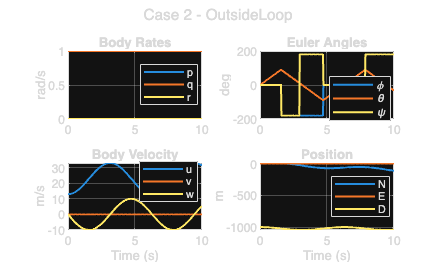

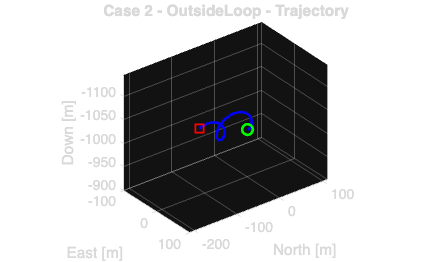

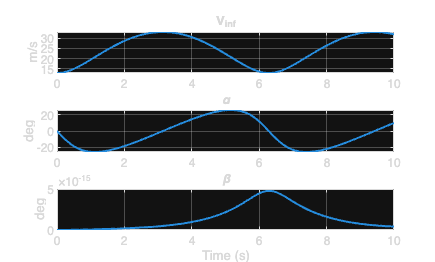

DLoops as expected, not a perfect circle/nbecause I didnt calculate the right force


out = run_flight_test(TC2, Mass, CG, J, wing, tailL, tailR, prop);

--------------------------------------------------
Case 3 - ForceField
--------------------------------------------------
  Model:            TESTER_Brown_Full_Sim
  Simulation Time:  10 s
  Initial Position: [0  0  -1000] m
  Initial Velocity: [13  0  0.25] m/s
  Initial Euler:    [0  0  0] deg
  Initial Omega:    [0  0  0] rad/s
  Gravity:          [0  0  9.81] m/s^2
  Fext_B:           [0  0  -4.7088] N
  Mext_B:           [0  0  0] N-m
 


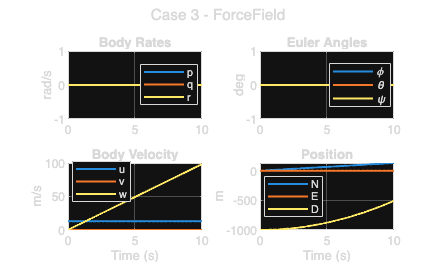

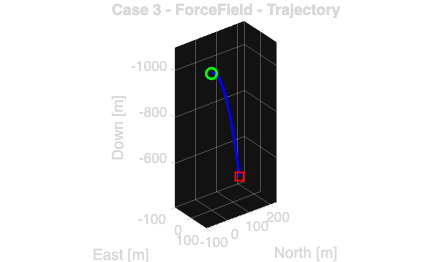

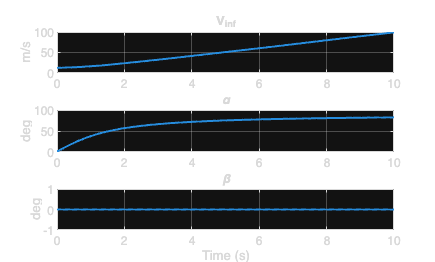

Drops due to gravity being stronger than the external force


run_flight_test(TC3, Mass, CG, J, wing, tailL, tailR, prop);

--------------------------------------------------
Case 4 - Roll Damping
--------------------------------------------------
  Model:            Brown_Full_Sim
  Simulation Time:  10 s
  Initial Position: [0  0  -1000] m
  Initial Velocity: [250  0  0] m/s
  Initial Euler:    [0  0  0] deg
  Initial Omega:    [0.3  0  0] rad/s
  Gravity:          [0  0  0] m/s^2
  Fext_B:           [0  0  0] N
  Mext_B:           [0  0  0] N-m
 


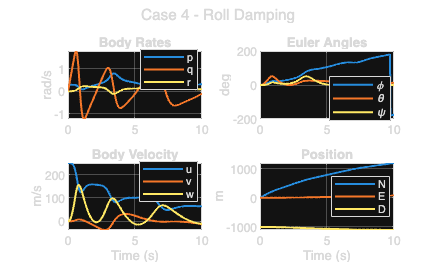

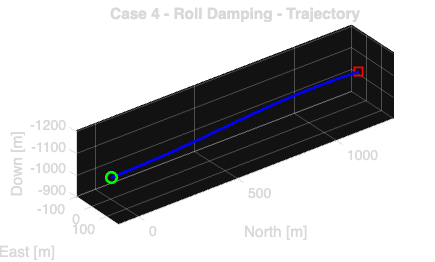

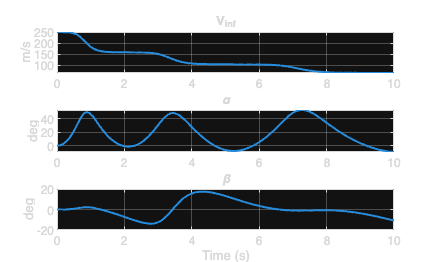

Stability seems to be different from prop plane likely due to V tail /nSeems like ti has a stability simmilar to a paper airplane that/n speeds while dropping then pitches and slows, before dropping again


run_flight_test(TC4, Mass, CG, J, wing, tailL, tailR, prop);

--------------------------------------------------
Case 5 - Beta to Yaw
--------------------------------------------------
  Model:            Brown_Full_Sim
  Simulation Time:  10 s
  Initial Position: [0  0  -1000] m
  Initial Velocity: [250  25  0] m/s
  Initial Euler:    [0  0  0] deg
  Initial Omega:    [0  0  0] rad/s
  Gravity:          [0  0  0] m/s^2
  Fext_B:           [0  0  0] N
  Mext_B:           [0  0  0] N-m
 


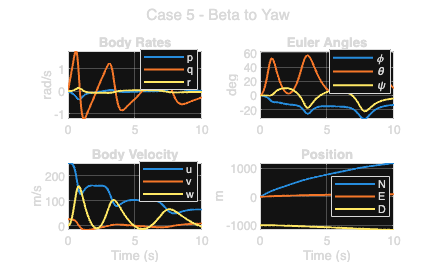

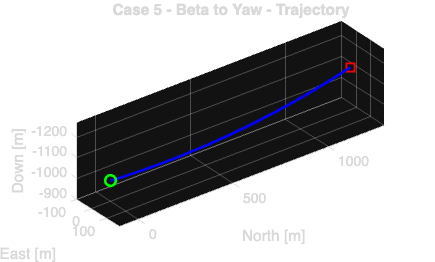

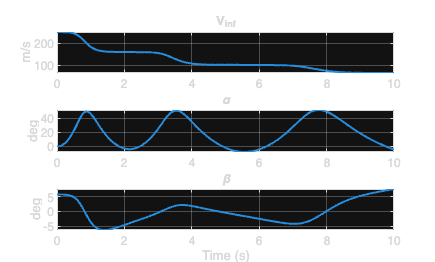

again lots of coupling in the axes that cant be simply explained due to V tial/n seeing the same paper airplane synamics here


run_flight_test(TC5, Mass, CG, J, wing, tailL, tailR, prop);

--------------------------------------------------
Final Validation - Stable 6DOF
--------------------------------------------------
  Model:            Brown_Full_Sim
  Simulation Time:  10 s
  Initial Position: [0  0  -1000] m
  Initial Velocity: [200  0.25  0.25] m/s
  Initial Euler:    [10  10  0] deg
  Initial Omega:    [0.01  1  0.01] rad/s
  Gravity:          [0  0  -9.81] m/s^2
  Fext_B:           [0  0  0] N
  Mext_B:           [0  0  0] N-m
 


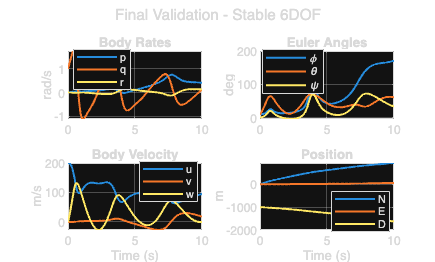

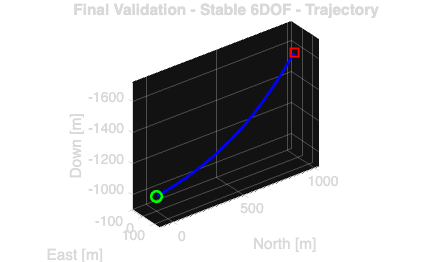

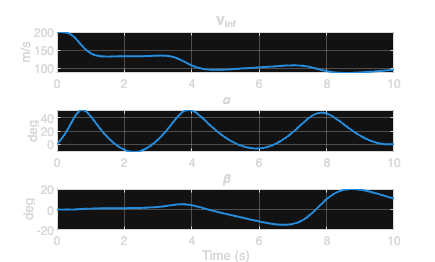

Motors seem to bring plane upwards - Aircraft is much more complex than simple prop plane/n Will take a long time to develop realistic test cases


run_flight_test(TC6, Mass, CG, J, wing, tailL, tailR, prop);

Overall, the flight sim behaves as expected. However, the model is very different from the prop plane model given in class. Test cases need to be adapted to this aircraft-specific configuration, including mass, inertia, thrust vectors, and aero surfaces. Specifically, the V-tail is providing a significant challenge in terms of different stability dynamics. That will be investigated in the next week.

This report validates that the physics engine is correct, but also brings up some critical needs for effective test cases, as well as reveals some natural modes of motion.  

Otherwise, I was able to get these two functions to open FlightGear; however, it's finicky because FlightGear is downloaded in a weird path on my computer, and so I get errors about where the aircraft data is located. I haven't been able to look around the aircraft yet, so there's still a lot of problems that need to be solved. I was able to load the loop-de-loop scenario too, and that's visually what happened in FlightGear, so I can confirm it worked. I don't know how to screenshot a video and put it in, but this is a screenshot clip from that. 

addpath("Flight_Gear");

cfg = fg_config();
fg_replay_from_out(out, cfg);

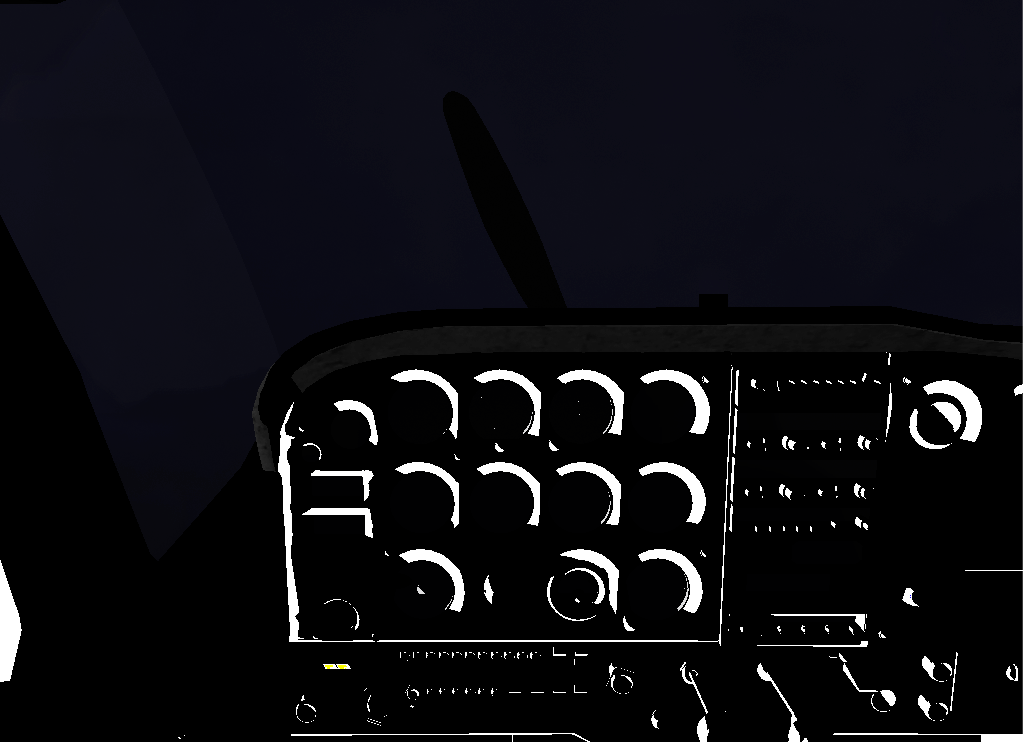

## Local functions

%% Local functions
function [Mass, CG, J, wing, tailL, tailR, prop, compData, tilt_angle] = init_from_full_sim()
flight_mode = 0;
tilt_angle = 90 * flight_mode;
rho = 1.225;

prop.hub_offset = 0.50;
prop.k_Thrust = 1.2e-4;
prop.k_Torque = 1.5e-5;
prop.k_torque = 1.5e-5;

compData = {
    'Fuselage',   'fuselage', 1500, [7.50, 2.00, 1.60], [ 0.00,  0.00,  0.00], [0, 0, 0];
    'Ballast',    'box',      250,  [0.60, 0.60, 0.60], [ 3.00,  0.00,  0.00], [0, 0, 0];
    'Main Wing',  'box',      450,  [1.50, 14.50, 0.20], [-0.50,  0.00, -0.60], [0, 0, 0];
    'L V-Tail',   'box',      90,   [1.40,  2.00, 0.08], [-3.50, -0.71, -0.91], [ 45, 0, 0];
    'R V-Tail',   'box',      90,   [1.40,  2.00, 0.08], [-3.50,  0.71, -0.91], [-45, 0, 0];
    'Boom L1',    'box',      55,   [4.50, 0.20, 0.20], [-0.20, -1.80, -0.45], [0, 0, 0];
    'Boom L2',    'box',      55,   [4.50, 0.20, 0.20], [-0.20, -4.20, -0.45], [0, 0, 0];
    'Boom L3',    'box',      55,   [4.50, 0.20, 0.20], [-0.20, -6.50, -0.45], [0, 0, 0];
    'Boom R1',    'box',      55,   [4.50, 0.20, 0.20], [-0.20,  1.80, -0.45], [0, 0, 0];
    'Boom R2',    'box',      55,   [4.50, 0.20, 0.20], [-0.20,  4.20, -0.45], [0, 0, 0];
    'Boom R3',    'box',      55,   [4.50, 0.20, 0.20], [-0.20,  6.50, -0.45], [0, 0, 0];
    'F-Arm L1',   'box',      5,    [0.40, 0.20, 0.20], [ 2.15, -1.80, -0.55], [0, tilt_angle, 0];
    'F-Arm L2',   'box',      5,    [0.40, 0.20, 0.20], [ 2.15, -4.20, -0.55], [0, tilt_angle, 0];
    'F-Arm L3',   'box',      5,    [0.40, 0.20, 0.20], [ 2.15, -6.50, -0.55], [0, tilt_angle, 0];
    'F-Arm R1',   'box',      5,    [0.40, 0.20, 0.20], [ 2.15,  1.80, -0.55], [0, tilt_angle, 0];
    'F-Arm R2',   'box',      5,    [0.40, 0.20, 0.20], [ 2.15,  4.20, -0.55], [0, tilt_angle, 0];
    'F-Arm R3',   'box',      5,    [0.40, 0.20, 0.20], [ 2.15,  6.50, -0.55], [0, tilt_angle, 0];
    'F-Rotor L1', 'crossprop',25,   [1.60, 0.15, 0.05], [ 1.95, -1.80, -0.45], [0, tilt_angle, 0];
    'F-Rotor L2', 'crossprop',25,   [1.60, 0.15, 0.05], [ 1.95, -4.20, -0.45], [0, tilt_angle, 0];
    'F-Rotor L3', 'crossprop',25,   [1.60, 0.15, 0.05], [ 1.95, -6.50, -0.45], [0, tilt_angle, 0];
    'F-Rotor R1', 'crossprop',25,   [1.60, 0.15, 0.05], [ 1.95,  1.80, -0.45], [0, tilt_angle, 0];
    'F-Rotor R2', 'crossprop',25,   [1.60, 0.15, 0.05], [ 1.95,  4.20, -0.45], [0, tilt_angle, 0];
    'F-Rotor R3', 'crossprop',25,   [1.60, 0.15, 0.05], [ 1.95,  6.50, -0.45], [0, tilt_angle, 0];
    'R-Rotor L1', 'crossprop',25,   [1.60, 0.15, 0.05], [-2.20, -1.80, -0.65], [0, 0, 0];
    'R-Rotor L2', 'crossprop',25,   [1.60, 0.15, 0.05], [-2.20, -4.20, -0.65], [0, 0, 0];
    'R-Rotor L3', 'crossprop',25,   [1.60, 0.15, 0.05], [-2.20, -6.50, -0.65], [0, 0, 0];
    'R-Rotor R1', 'crossprop',25,   [1.60, 0.15, 0.05], [-2.20,  1.80, -0.65], [0, 0, 0];
    'R-Rotor R2', 'crossprop',25,   [1.60, 0.15, 0.05], [-2.20,  4.20, -0.65], [0, 0, 0];
    'R-Rotor R3', 'crossprop',25,   [1.60, 0.15, 0.05], [-2.20,  6.50, -0.65], [0, 0, 0];
};

% format: {name, normal_vec, CL0, e, i, CD0, CDa, a0, CM0, CMa, CLa}
aeroData = {
    'Main Wing', [0; 0; -1],                 0.05, 0.9, 0.05, 0.01, 1, 0.05, -0.05, 0, 0.01;
    'L V-Tail',  [0; sind(45); -cosd(45)],   0,    0.8, 0,    0.01, 1, 0,     0,    0, 0.01;
    'R V-Tail',  [0; -sind(45); -cosd(45)],  0,    0.8, 0,    0.01, 1, 0,     0,    0, 0.01;
};

N = size(compData, 1);

Mtot = 0;
CG_row = [0, 0, 0];
for i = 1:N
    m = compData{i, 3};
    pos = compData{i, 5};
    Mtot = Mtot + m;
    CG_row = CG_row + m * pos;
end
CG_row = CG_row / Mtot;

I_total = zeros(3,3);
for i = 1:N
    type = compData{i, 2};
    m = compData{i, 3};
    dim = compData{i, 4};
    pos = compData{i, 5};
    eul = compData{i, 6} * (pi/180);

    if strcmp(type, 'crossprop')
        D = dim(1); W = dim(2); T = dim(3);
        Ixx1 = (1/12)*(m/2)*(W^2 + T^2);
        Iyy1 = (1/12)*(m/2)*(D^2 + T^2);
        Izz1 = (1/12)*(m/2)*(D^2 + W^2);
        Ixx2 = (1/12)*(m/2)*(D^2 + T^2);
        Iyy2 = (1/12)*(m/2)*(W^2 + T^2);
        Izz2 = (1/12)*(m/2)*(D^2 + W^2);
        I_local = diag([Ixx1+Ixx2, Iyy1+Iyy2, Izz1+Izz2]);
    else
        xL = dim(1); yL = abs(dim(2)); zL = dim(3);
        I_local = diag([(1/12)*m*(yL^2 + zL^2), (1/12)*m*(xL^2 + zL^2), (1/12)*m*(xL^2 + yL^2)]);
    end

    phi = eul(1); theta = eul(2); psi = eul(3);
    Rx = [1 0 0; 0 cos(phi) -sin(phi); 0 sin(phi) cos(phi)];
    Ry = [cos(theta) 0 sin(theta); 0 1 0; -sin(theta) 0 cos(theta)];
    Rz = [cos(psi) -sin(psi) 0; sin(psi) cos(psi) 0; 0 0 1];
    R = Rz * Ry * Rx;

    I_rot = R * I_local * R';
    d = (pos - CG_row)';
    I_total = I_total + I_rot + m * ((d'*d)*eye(3) - (d*d'));
end

Mass = Mtot;
CG = CG_row';
J = I_total;

wing.c = compData{3, 4}(1); wing.b = compData{3, 4}(2); wing.S = wing.b * wing.c;
wing.half_rho_S = 0.5 * rho * wing.S; wing.pos = (compData{3, 5})';
wing.n = aeroData{1, 2}; wing.CL0 = aeroData{1, 3}; wing.e = aeroData{1, 4};
wing.i = aeroData{1, 5}; wing.CD0 = aeroData{1, 6}; wing.CDa = aeroData{1, 7};
wing.a0 = aeroData{1, 8}; wing.CM0 = aeroData{1, 9}; wing.CMa = aeroData{1, 10};
wing.CLa = aeroData{1, 11}; wing.AR = wing.b / wing.c;

tailL.c = compData{4, 4}(1); tailL.b = compData{4, 4}(2); tailL.S = tailL.b * tailL.c;
tailL.half_rho_S = 0.5 * rho * tailL.S; tailL.pos = (compData{4, 5})';
tailL.n = aeroData{2, 2}; tailL.CL0 = aeroData{2, 3}; tailL.e = aeroData{2, 4};
tailL.i = aeroData{2, 5}; tailL.CD0 = aeroData{2, 6}; tailL.CDa = aeroData{2, 7};
tailL.a0 = aeroData{2, 8}; tailL.CM0 = aeroData{2, 9}; tailL.CMa = aeroData{2, 10};
tailL.CLa = aeroData{2, 11}; tailL.AR = tailL.b / tailL.c;

tailR.c = compData{5, 4}(1); tailR.b = compData{5, 4}(2); tailR.S = tailR.b * tailR.c;
tailR.half_rho_S = 0.5 * rho * tailR.S; tailR.pos = (compData{5, 5})';
tailR.n = aeroData{3, 2}; tailR.CL0 = aeroData{3, 3}; tailR.e = aeroData{3, 4};
tailR.i = aeroData{3, 5}; tailR.CD0 = aeroData{3, 6}; tailR.CDa = aeroData{3, 7};
tailR.a0 = aeroData{3, 8}; tailR.CM0 = aeroData{3, 9}; tailR.CMa = aeroData{3, 10};
tailR.CLa = aeroData{3, 11}; tailR.AR = tailR.b / tailR.c;

idx_FR = find(contains(compData(:,1), 'F-Rotor R'));
idx_FL = find(contains(compData(:,1), 'F-Rotor L'));
idx_RR = find(contains(compData(:,1), 'R-Rotor R'));
idx_RL = find(contains(compData(:,1), 'R-Rotor L'));

prop.posFR = cell2mat(compData(idx_FR, 5));
prop.posFL = cell2mat(compData(idx_FL, 5));
prop.posRR = cell2mat(compData(idx_RR, 5));
prop.posRL = cell2mat(compData(idx_RL, 5));
prop.Lspin_dir = [-1; 1; -1];
prop.Rspin_dir = [1; -1; 1];
end

function out = run_flight_test(Case, Mass, CG, J, wing, tailL, tailR, prop)
if isscalar(Case.g)
    g_vec = [0;0;Case.g];
else
    g_vec = Case.g(:);
end
disp('--------------------------------------------------');
disp(Case.name);
disp('--------------------------------------------------');
fprintf('  Model:            %s\n', Case.model);
fprintf('  Simulation Time:  %g s\n', Case.t_stop);
fprintf('  Initial Position: [%g  %g  %g] m\n', Case.pos_init);
fprintf('  Initial Velocity: [%g  %g  %g] m/s\n', Case.V_init);
fprintf('  Initial Euler:    [%g  %g  %g] deg\n', Case.eul_init_deg);
fprintf('  Initial Omega:    [%g  %g  %g] rad/s\n', Case.omega_init);
fprintf('  Gravity:          [%g  %g  %g] m/s^2\n', g_vec);
fprintf('  Fext_B:           [%g  %g  %g] N\n', Case.Fext_B);
fprintf('  Mext_B:           [%g  %g  %g] N-m\n', Case.Mext_B);
disp(' ');


assignin('base', 'Mass', Mass);
assignin('base', 'm', Mass);
assignin('base', 'CG', CG);
assignin('base', 'J', J);
assignin('base', 'wing', wing);
assignin('base', 'tailL', tailL);
assignin('base', 'tailR', tailR);
assignin('base', 'prop', prop);

assignin('base', 'g', g_vec);
assignin('base', 'pos_init', Case.pos_init);
assignin('base', 'V_init', Case.V_init);
assignin('base', 'eul_init', deg2rad(Case.eul_init_deg(:)));
assignin('base', 'omega_init', Case.omega_init);
assignin('base', 'Fext_B', Case.Fext_B);
assignin('base', 'Mext_B', Case.Mext_B);
assignin('base', 'Motor_RPMs', Case.Motor_RPMs);
assignin('base', 'Tilt_angles', Case.Tilt_angles);

out = sim(Case.model, 'StopTime', num2str(Case.t_stop), 'ReturnWorkspaceOutputs', 'on');

[omega, t_omega] = get_ts_data(out, 'omega');
[eul, t_eul] = get_ts_data(out, 'eul');
[v_b, t_v_b] = get_ts_data(out, 'v_b');
[position, t_pos] = get_ts_data(out, 'position');
[vinf, t_vinf] = get_ts_data(out, 'vinf');
[alpha, t_alpha] = get_ts_data(out, 'alpha');
[beta, t_beta] = get_ts_data(out, 'beta');

if ~isempty(eul)
    eul = rad2deg(eul);
end
if ~isempty(alpha)
    alpha = rad2deg(alpha);
end
if ~isempty(beta)
    beta = rad2deg(beta);
end

figure('Name', Case.name);
sgtitle(Case.name);

subplot(2,2,1);
plot(t_omega, omega, 'LineWidth', 1.5); grid on;
title('Body Rates'); ylabel('rad/s'); legend('p','q','r','Location','best');

subplot(2,2,2);
plot(t_eul, eul, 'LineWidth', 1.5); grid on;
title('Euler Angles'); ylabel('deg'); legend('\phi','\theta','\psi','Location','best');

subplot(2,2,3);
plot(t_v_b, v_b, 'LineWidth', 1.5); grid on;
title('Body Velocity'); ylabel('m/s'); xlabel('Time (s)'); legend('u','v','w','Location','best');

subplot(2,2,4);
plot(t_pos, position, 'LineWidth', 1.5); grid on;
title('Position'); ylabel('m'); xlabel('Time (s)'); legend('N','E','D','Location','best');

if ~isempty(position)
    X = position(:,1); Y = position(:,2); Z = position(:,3);

    figure('Name', [Case.name, ' Trajectory']);
    plot3(X, Y, Z, 'b-', 'LineWidth', 2); grid on; hold on;
    set(gca, 'ZDir', 'reverse', 'YDir', 'reverse');
    plot3(X(1), Y(1), Z(1), 'go', 'MarkerSize', 8, 'LineWidth', 2);
    plot3(X(end), Y(end), Z(end), 'rs', 'MarkerSize', 8, 'LineWidth', 2);
    xlabel('North [m]'); ylabel('East [m]'); zlabel('Down [m]');

    title([Case.name, ' - Trajectory']);
    axis equal;
    xlim([min(X)-100,max(X)+100]);
    ylim([min(Y)-100,max(Y)+100]);
    zlim([min(Z)-100,max(Z)+100]);
end

if ~isempty(vinf) || ~isempty(alpha) || ~isempty(beta)
    figure('Name', [Case.name, ' Air Data']);

    subplot(3,1,1);
    plot(t_vinf, vinf, 'LineWidth', 1.5); grid on;
    title('V_{inf}'); ylabel('m/s');

    subplot(3,1,2);
    plot(t_alpha, alpha, 'LineWidth', 1.5); grid on;
    title('\alpha'); ylabel('deg');

    subplot(3,1,3);
    plot(t_beta, beta, 'LineWidth', 1.5); grid on;
    title('\beta'); ylabel('deg'); xlabel('Time (s)');
end
disp(Case.note);
end

function [data, t] = get_ts_data(out, var_name)
data = [];
t = [];

try
    ts = out.get(var_name);
catch
    return;
end

if isempty(ts)
    return;
end

t = ts.Time;
data = squeeze(ts.Data);

if isempty(data)
    return;
end

if isvector(data)
    data = data(:);
elseif size(data,1) <= 3 && size(data,2) > size(data,1)
    data = data';
end
end
